f = @(x, y) y - 3*x;
g = @(x) 7*exp(x) + 3*x + 3;

y0 = 10;
x0 = 0;
xn = 3;

dx = 0.5;

x = x0 : dx : xn;
y = zeros(size(x));
y1 = zeros(size(x));
y2 = zeros(size(x));
y_exact = g(x);

y(1) = y0;
y1(1) = y0;
y2(1) = y0;

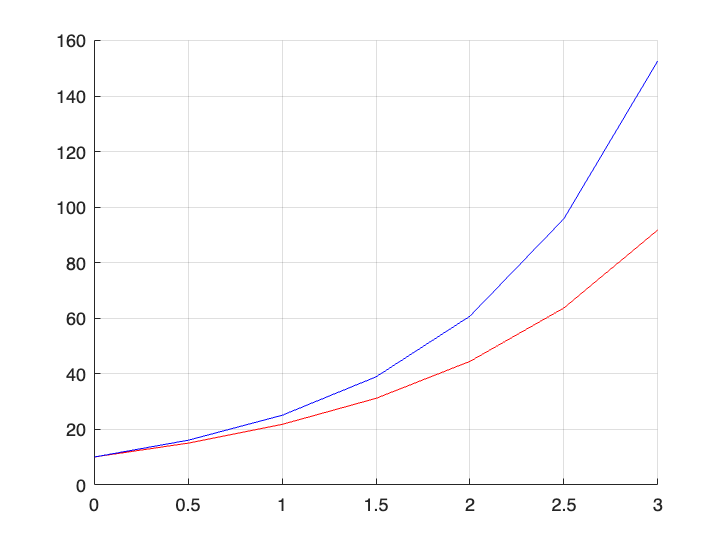

for i = 1:length(x) - 1
    y(i + 1) = y(i) + dx*(f(x(i), y(i)));
end

% This array is defined as percentage. If
% decimals wanted, remove * 100.
errors = (abs(y - y_exact)./y_exact) * 100;

% This array represents the slope given by f(x, y)
m = f(x, y);

figure;
hold on;
grid on;
plot(x, y, 'r');
plot(x, y_exact, 'b');

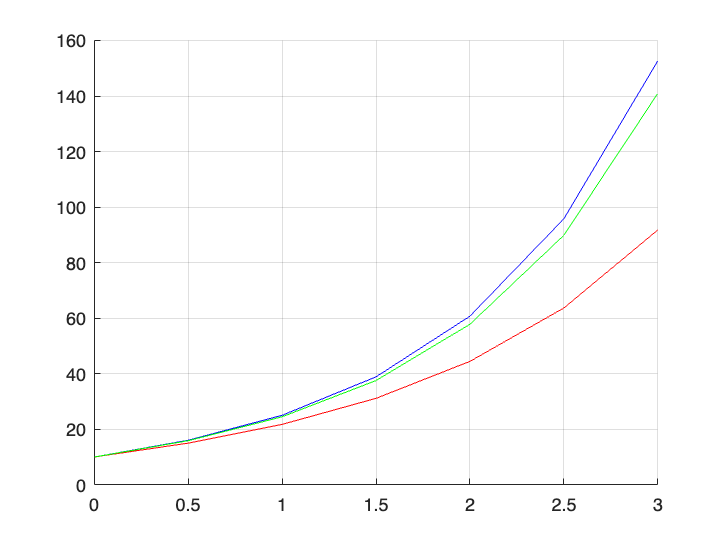

% My own improvment using a1 and a2
% It's name: Andrew's method
a2 = 5/6;
a1 = 1 - a2;
q = 1/(2*a2);

for i = 1:length(x) - 1
    k1 = f(x(i), y(i));
    k2 = f(x(i) + q*dx, y(i) + q*k1*dx);
    y(i + 1) = y(i) + (a2*k2 + a1*k1)*dx;
end

plot(x, y, 'g');
hold off;

% Can't submit a *.m file so here's the function:

function yapprox = RK2 (m, x0, xf, y0, step, a2)
    x = x0:step:xf;
    y = zeros(size(x));
    y(1) = y0;
    
    if a2 ~= 0
        q = 1/(2*a2);
    else
        q = 0;
    end
     
    a1 = 1 - a2;

    for i = 1:length(x) - 1
        k1 = m(x(i), y(i));
        k2 = m(x(1) + q*step, y(i) + q*step*k1);

        y(i + 1) = y(i) + (a1*k1 + a2*k2)*step;
    end

    yapprox = y;
end